# Model AUTOSAR Runnables Using Exported Functions

Use Simulink® exported functions to model AUTOSAR runnables.

## Multiple Periodic Runnables Configured for Function Export

Open the example model `autosar_swc_expfcns.slx`.

open_system('autosar_swc_expfcns')

The model shows the implementation of an AUTOSAR atomic software component (ASWC) using export-function modeling. Export-function models are Simulink models that generate code for independent functions. You can integrate the independent function code with an external environment and scheduler. Functions typically are defined using Function-Call Subsystem and Simulink Function blocks.

This model implements three AUTOSAR periodic runnables using Function-Call Subsystem blocks that have periodic rates. The runnables have sample rates of 1 second, 1 second, and 10 seconds, respectively. To display color coded sample rates with annotations and a legend, on the **Debug** tab, select **Diagnostics > Information Overlays > Colors**.

Simulink signal lines model AUTOSAR inter-runnable variables (IRVs), which connect the runnables.

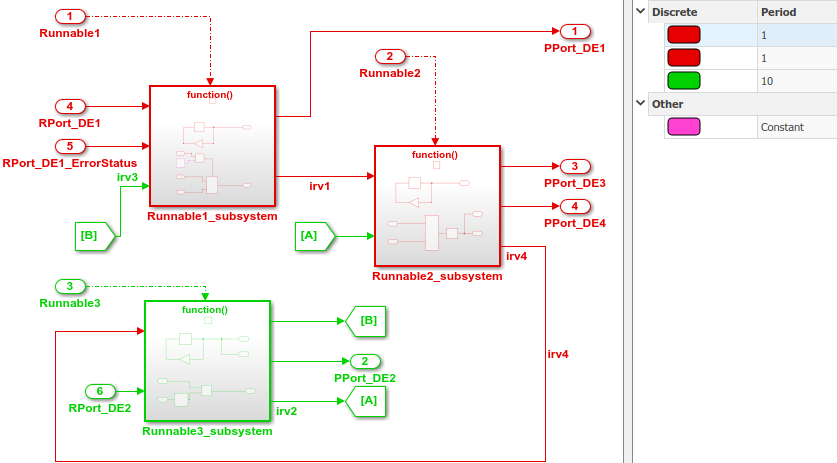

## Generate AUTOSAR Component Code and XML Descriptions (Embedded Coder)

If you have Simulink Coder and Embedded Coder software, you can generate algorithmic C code and AUTOSAR XML (ARXML) component descriptions. You can test the generated code in Simulink or integrate the code and descriptions into an AUTOSAR run-time environment.

For example, to build the `autosar_swc_expfcns` component model, open the model. Press **Ctrl+B** or enter the MATLAB command `slbuild('autosar_swc_expfcns')`. When the build completes, a code generation report opens.

In the code generation report, select the **Code Interface Report** section, and examine the **Entry-Point Functions** table. 

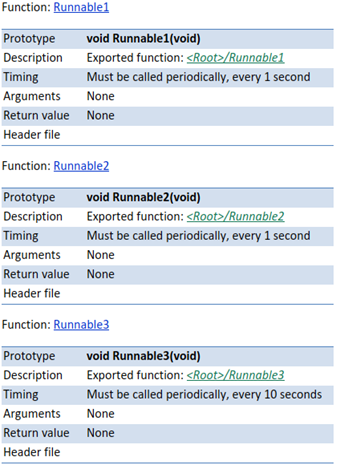

In the generated code, each root-level function-call Inport block generates a void-void function. From generated file `autosar_swc_expfcns.c`, here is the generated code for `Runnable1`.

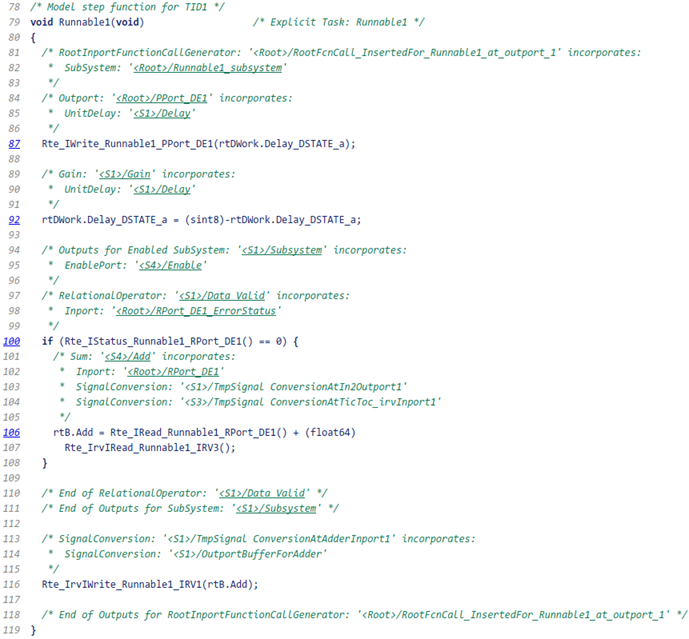

## Related Links

[Export-Function Models](docid:simulink_ug.bt170no)

*Copyright 2020 The MathWorks, Inc.*